addpath functions/SETUP/
addpath functions/ACT/
addpath functions/SENSE/

clear all
clc

robotPi = SETUP_pi("192.168.16.66");
neo = SETUP_gps(robotPi);

while 1
    [X,Y,heading] = SENSE_gps(neo);

waypoints = [-71.2642324,42.2931473;
              -71.2641922,42.2931423;
              -71.2641345,42.2931433;
              -71.264101,42.2931453;
              -71.2640621,42.2931532;
              -71.2640246,42.2931582;
              -71.263987,42.2931701;
              -71.2639468,42.293179;
              -71.2639052,42.2931929;
              -71.263873,42.2932078;
              -71.2638395,42.2932207;
              -71.2637885,42.2932415;
              -71.2637604,42.2932604;
              -71.2637269,42.2932792;
              -71.2636933,42.293308;
              -71.2636638,42.2933348;
              -71.263641,42.2933546;
              -71.2636182,42.2933764;
              -71.2635941,42.2933973;
              -71.2635659,42.29343;
              -71.2635565,42.2934479;
              -71.2635364,42.2934776;
              -71.263515,42.2935114;
              -71.2635002,42.293557;
              -71.2634908,42.2935887;
              -71.2634855,42.2936165;
              -71.2634922,42.2936493;
              -71.2634948,42.2936731;
              -71.2635096,42.2936979;
              -71.2635431,42.2937237;
              -71.2635686,42.2937375;
              -71.2636222,42.2937564;
              -71.2636705,42.2937614;
              -71.2637201,42.2937663;
              -71.2637631,42.2937653;
              -71.263806,42.2937584;
              -71.2638502,42.2937494;
              -71.2638905,42.2937415;
              -71.2639307,42.2937326;
              -71.2639776,42.2937177;
              -71.2640179,42.2937048;
              -71.2640581,42.293685;
              -71.2640957,42.2936701;
              -71.2641185,42.2936582;
              -71.264148,42.2936443;
              -71.2641708,42.2936294;
              -71.2642003,42.2936106;
              -71.2642204,42.2935907;
              -71.2642485,42.2935689;
              -71.264278,42.2935441;
              -71.2643022,42.2935193;
              -71.2643223,42.2934945;
              -71.2643451,42.2934657;
              -71.2643652,42.293437;
              -71.2643786,42.2934082;
              -71.2643947,42.2933834;
              -71.2644068,42.2933546;
              -71.2644162,42.2933278;
              -71.2644229,42.2932961;
              -71.2644215,42.2932723;
              -71.2644148,42.2932495;
              -71.2644001,42.2932257;
              -71.2643827,42.2932028;
              -71.2643585,42.293187;
              -71.2643277,42.2931711;
              -71.2642928,42.2931622;
              -71.2642646,42.2931542;
              -71.2642324,42.2931473;
];

controller = controllerPurePursuit("Waypoints",waypoints,"DesiredLinearVelocity",1,"MaxAngularVelocity",1*pi);
%can add LookaheadDistance in m

% X = -71.2639000000000
% Y = 42.2936000000000
% heading = 102.689400000000

%vel m/s
%ang rad/s
[vel, angvel] = controller([X, Y, heading]) 

vel = 1

angvel = -0.0600

% controller([xpos, ypos, theta]) 
% theta in radians measured from x axis

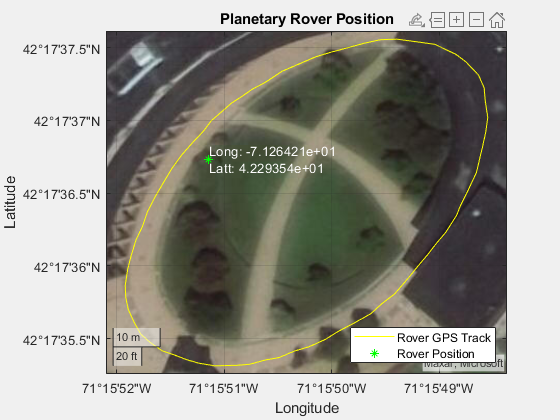

% Create a stand alone figure to plot GPS rover position data in
gpsRoverPlot=figure('Name','Rover Position','NumberTitle','off','Visible','on');
% Zoom down the plot to the Olin Oval coordinates in Latitude and Longitude
geolimits([42.29246 42.29418],[-71.26537 -71.26258])
% Plot out a trail line bewteen two waypoints just o demo line drawing
geoplot(waypoints(:,2),waypoints(:,1),'y-','DisplayName','Rover GPS Track')
hold on;
% plot rover poition, you can change this line to plot roverX and RoverY 
%geo plot(latt, long)
geoplot(Y, X, 'g*','DisplayName','Rover Position')
text(Y,X,{sprintf('Long: %d', X),sprintf('Latt: %d', Y)},'Color','w')
hold off
% Import a satellite photo basemap to draw on
geobasemap satellite
legend('Location','southeast')
movegui(gpsRoverPlot,'south');
title('Planetary Rover Position')